**INDEX**

- **Scalar **

- **Vector **

- **Row Vector**

- **Continuous Row Vectors AND linspace()**

- ** Column Vectors AND Continuous Column Vectors**

- **Matrix AND Transpose of Matrix**

- **Extracting values from a Matrix**

- **Changing value in 1-D & 2-D Array**

- **More Array Creation Functions**

Arrays are used throughout MATLAB. MATLAB is an abbreviation of **MAT**rix **LAB**oratory. 

A **Matrix** is a 2D-Array.

All **MATLAB **variables are arrays. This means that each numeric variable can contain multiple numbers. You can use arrays to store related data in one variable.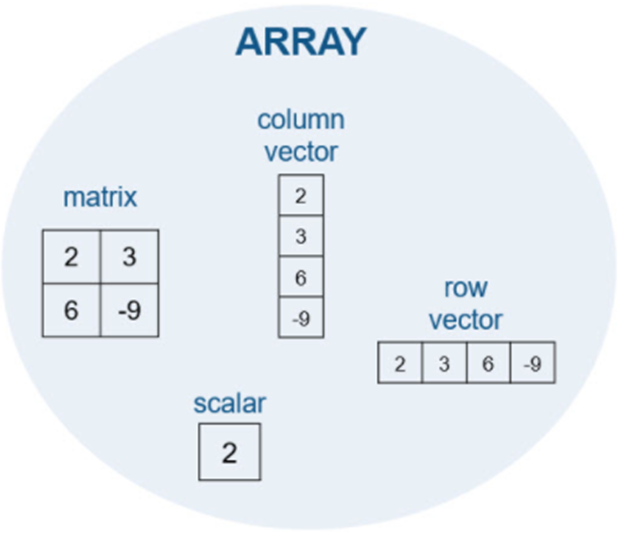

# **Scalar**

A single number, called a ***scalar***, is actually a 1-by-1 array OR **point **array, meaning it contains 1 row and 1 column.

scalar = 5 %check workspace variables to see x

scalar = 5

# **Vector**

A vector is a **1-by-n** or **n-by-1** type array, meaning it is a 1 Dimensional array.

vector = [21 32 34 76]

vector =     21    32    34    76


 Vectors only require one index to find a specific value. *For example:*

vector(1)

ans = 21

# **Row Vector**

Separating numbers using commas or spaces inside square brackets combines the numbers into a ***row vector****. *Representation : 1-by-**n**

row_vector_1 = [7 9]     % 1-by-2

row_vector_1 =      7     9


row_vector_2 = [1, 2, 3] % 1-by-3

row_vector_2 =      1     2     3


# **Continuous Row Vectors**

We can also use **colon**(**:**) to create longer vectors, that are continuous. We don't have to use square brackets when creating continuous row vectors.

cont_row_vector_1 = 1:4

cont_row_vector_1 =      1     2     3     4


We can also specify what gap we want between two values *(default gap is 1).*

cont_row_vector_2 = 0:0.75:3 %the middle value is the gap

cont_row_vector_2 =          0    0.7500    1.5000    2.2500    3.0000


If suppose we give an upper limit which is not a multiple of the gap, then we just get the highest multiple less than the upper limit. *For example:*

cont_row_vector_3 = 1:0.5:3.25 %we get max value 3 

cont_row_vector_3 =     1.0000    1.5000    2.0000    2.5000    3.0000


# **Linspace()**

If suppose we know the **number of elements we want in a vector** *(instead of the gap between each element), *we can use the `linspace` function:

`    linspace``(``first``,``last``,``number_of_elements(``N``)``)`

`Using this we get ``N linearly spaced ``data points.`

In this we specify our starting and ending number and the number of elements we want. What we get is the number of elements we want with equal gaps. E.g:

cont_row_vector_4 = linspace(1, 3, 7)

cont_row_vector_4 =     1.0000    1.3333    1.6667    2.0000    2.3333    2.6667    3.0000


cont_row_vector_5 = linspace(1, 10, 5)

cont_row_vector_5 =     1.0000    3.2500    5.5000    7.7500   10.0000


See the last row vector. We can imagine it like this. We need 5 terms. The first term is 1. remain 4 terms are given by evenly splitting the difference between the first and last element.

So, the gap = (10 - 1)/4 = 2.25. Hence, the remaining four terms have multiples of 2.25 added to 1.

NOTE that the elements we get using *linspace() *are indexed like regular vectors.

# **Column Vector**

Separating numbers by semicolons creates a ***column vector****. *Representation : **n**-by-1

column_vector = [4 ; 5 ; 6] % 3-by-1

column_vector =      4
     5
     6


# **Continuous Column Vectors**

We can create column vectors in a single command by creating a row vector and transposing it all on one line. 

cont_column_vector = (1:2:7)'

cont_column_vector =      1
     3
     5
     7


Note the use of parentheses here to specify the order of operations.

# **Matrix**

We can combine **spaces** and **semicolons** to create a *matrix*, which is an array with multiple rows and columns. When entering a matrix, we must enter them row by row.

matrix = [1 2 3 ; 4 5 6 ; 7 8 9]

matrix =      1     2     3
     4     5     6
     7     8     9


# **Transpose of a Matrix**

Transpose of a matrix is given by:

matrix = matrix'

matrix =      1     4     7
     2     5     8
     3     6     9


# **Extracting Singular Values from a Matrix**

SYNTAX : matrixName(*row_number, column_number*)

matrix(2,3)

ans = 8

This command finds the value present in the 2nd row and the 3rd column of the matrix.

We can also use the **'end' **keyword to obtain a value present in the last row/column of a matrix.

matrix(end,end - 1) 

ans = 6

We get the value in the last row and the 2nd last column.

If you only use **one index with a matrix**, it will traverse down each column in order. For example: 

matrix(8)

ans = 8

This will give us the second element of the third column.

# **Extracting Multiple Values from a Matrix**

SYNTAX :

            *matrixName( ****:**** , column_number)*

This means elements in all rows and a specific column_number. This would be used to extract a **specific COLUMN of the matrix.**

matrix( : , 2)

ans =      4
     5
     6


            *matrixName( row_number, ****:****)*

This means elements in a specific row_number and all columns. This would be used to extract a **specific ROW of the matrix.**

matrix(3 , : )

ans =      3     6     9


**NOTE : The colon( : ) when used alone, means taking the entire range, without any restrictions.**

# **Changing values in a 1-D Array (Vector) and 2-D Array (Matrix)**

**1-D Array**

vector = matrix(1, : )

vector =      1     4     7


vector(1) = 76

vector =     76     4     7


**2-D Array**

Using two indices

matrix(1, 2) = 45

matrix =      1    45     7
     2     5     8
     3     6     9


Using single index

matrix(7) = 21

matrix =      1    45    21
     2     5     8
     3     6     9


NOTE : This method of indexing proceeds column wise. For example, if we have a 3 by 3 matrix, the first 3 elements will be the first column, and the 4th element will be the first element of the second column.

# **Creating Random Arrays**

**randi(***[min, max], dimension_1, dimension_2...) ***function**

This *randi()* function gives us **uni/multidimensional arrays** with random **integers***(because of which they are called pseudorandom, as they are not truly random)* within the specified range.

matrix = randi([-20, 20], 4, 5)

matrix =     11    -1    12     4    10
    18   -20    -8   -10    -2
   -15    -7     1     6   -17
     3   -14   -14     8   -11


This indicates the elements of the matrix will be between **-20** and **20**.

Also, the *number of rows* are **4** and the *number of columns* are **5**.

**NOTE : **We can also just put one number after the square brackets, to form a square matrix.

**rand(***rows, columns ***OR ***square size) ***function**

This function returns a matrix with random elements ***uniformly*** distributed on the interval (0, 1).

matrix = rand(2, 3)

matrix =     0.9133    0.8258    0.9961
    0.1524    0.5383    0.0782


If it is a square matrix, we can just put one argument 'n' and we will get an n-by-n random matrix.

matrix = rand(4)

matrix =     0.4427    0.7749    0.3998    0.9106
    0.1067    0.8173    0.2599    0.1818
    0.9619    0.8687    0.8001    0.2638
    0.0046    0.0844    0.4314    0.1455


**randn(***rows, columns ***OR ***square size) ***function**

This function returns a matrix with ***normally*** distributed pseudo-random elements having zero mean and variance one.

**Difference between ***rand()*** and ***randn()*

*rand()* function gives elements which have **uniform** distribution over (0, 1).

**Uniform** distributions are **probability distributions with equally likely outcomes**.

*randn()* function gives elements which have normal distribution over (0, 1).

Normal distribution is **a probability distribution that is symmetric about the mean**, showing that data near the mean are more frequent in occurrence than data far from the mean.

# **More Array Creation Functions**

**zeros(*****[****rows, columns/square size]***) function**

This function creates a matrix which has zeros at all positions

zero_matrix = zeros(2, 3)

zero_matrix =      0     0     0
     0     0     0


**ones(*****[****rows, columns/square size]***) function**

This function creates a matrix which has ones at all positions

one_matrix = ones(3)

one_matrix =      1     1     1
     1     1     1
     1     1     1



matrix = randi(2, 3)

matrix =      1     2     2
     2     1     1
     2     2     2


duplicate_matrix = ones(size(matrix))

duplicate_matrix =      1     1     1
     1     1     1
     1     1     1


%this command is useful for creating a matrix in one line

**eye(*****[****rows, columns/square size]***) function**

This function creates an ***identity*** matrix.

eye(3)

ans =      1     0     0
     0     1     0
     0     0     1


Although indentity matrices are ALWAYS square even for non-square matrices, matlab allows us to create **portions of an identity matrix**.

eye(3,2)

ans =      1     0
     0     1
     0     0
